# Matpower Simulation - 6 bus grid: sensitivity to noise

Matpower is an open source simulation engine and optimal power flow calculator for MATLAB. More info here: [https://matpower.org/.](https://matpower.org/.)

We want to use it to simulate the behaviour of our identification algorithm on real networks.

## Network definition

We choose a standard testbed. 

clear all
close all
clc
rng(11);

We load the data and we define the simulation setup to be used.

define_constants;
samples = 50;
noise_v_sd = [0, 1e-6, 1e-5, 1e-4, 1e-3];
noise_i_sd = [0, 1e-6, 1e-5, 1e-4, 1e-3];
random_load_power_cv = 0.1;
mpc = loadcase('case6ww_modified');

We define useful constants and we derive the impedence matrix.

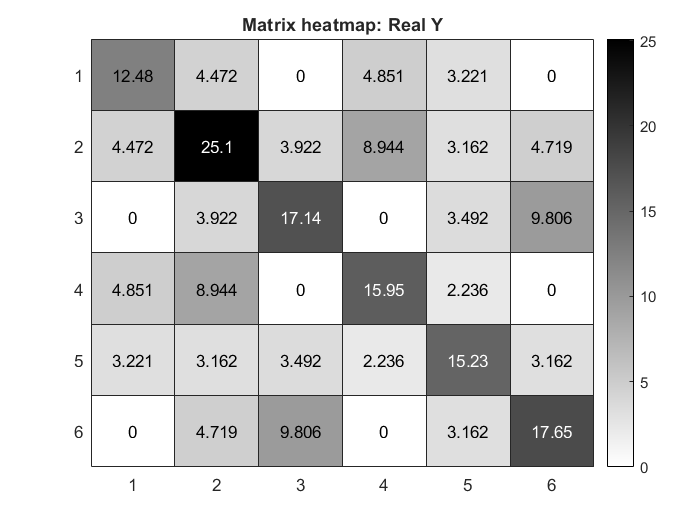

Y = full(makeYbus(mpc));
load_mask = mpc.bus(:, BUS_TYPE) == PQ;
controllable_mask = mpc.bus(:, BUS_TYPE) == PV;
n = size(mpc.bus, 1);
n_gen = size(mpc.gen, 1);
n_controllable = sum(controllable_mask);
n_load = n - n_gen;
matrix_heatmap(Y, 'Real Y');

We check that the admittance matrix is in fact Laplacian.

max(sum(Y, 2))

ans = 2.2204e-16 + 1.7764e-15i

issymmetric(Y)

ans = logical
   1


Looks like it is, in fact!

## Grid simulation

We choose an arbitrary number of time steps and we simulate the evolution of the grid over those instants. 

At the moment, active and reactive power requirements for loads are random, but we will shortly move towards real profiles.


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.02 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    194.8             161.0
Loads              3     Load                   189.3             143.8
  Fixed            3       Fixed                189.3             143.8
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

Froebius norm for RLS1 is 0.016324
Max norm for RLS1 is 0.0087686


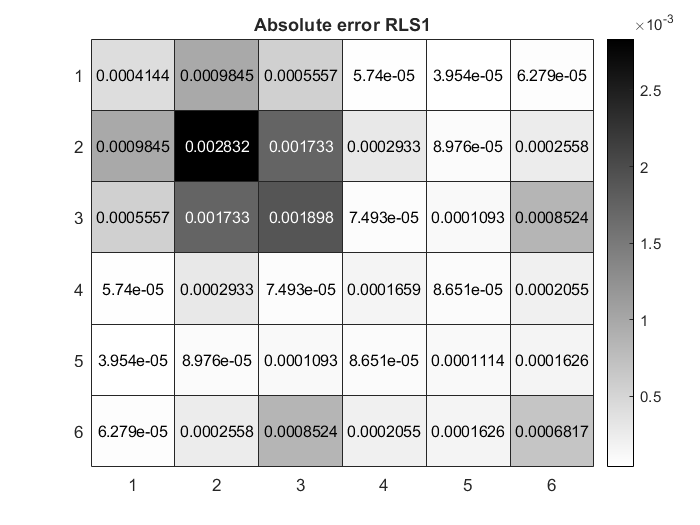

Froebius norm for RLS2 is 0.001097
Max norm for RLS2 is 0.00074717


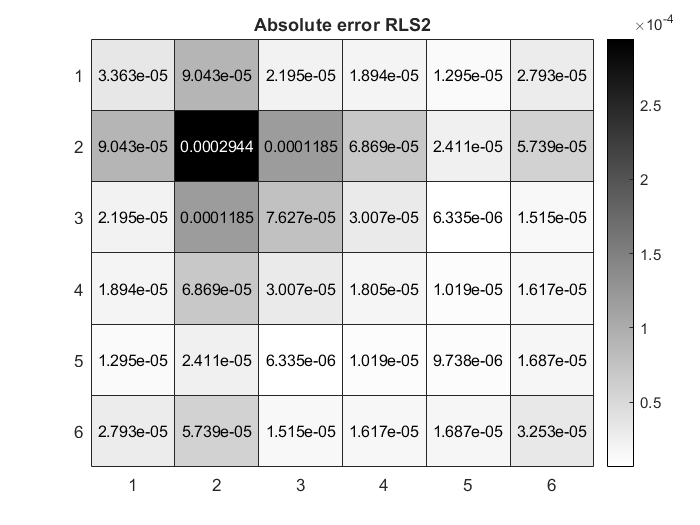

Difference between estimated and reconstruced matrix 0

MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.428046e+01     1.218e+00     1.000e+00     0.000e+00     3.888e+01  
    1          38    6.104609e+01     9.702e-01     1.000e+00     2.280e+00     7.777e+03  
    2          61    6.104609e+01     8.272e-01     2.401e-01     1.748e+00     7.777e+03  
    3          84    6.104609e+01     8.746e-01     2.401e-01     1.307e+00     7.777e+03  
    4         107    6.104609e+01     9.241e-01     2.401e-01     6.600e-01     7.777e+03  
    5         129    6.104608e+01     8.445e-01     3.430e-01     7.837e-01     7.777e+03  
    6         152    6.104608e+01     8.675e-01     2.401e-01     5.215e-01     7.777e+03  
  

Froebius norm for DoE is 7.9455e-05
Max norm for DoE is 3.3128e-05


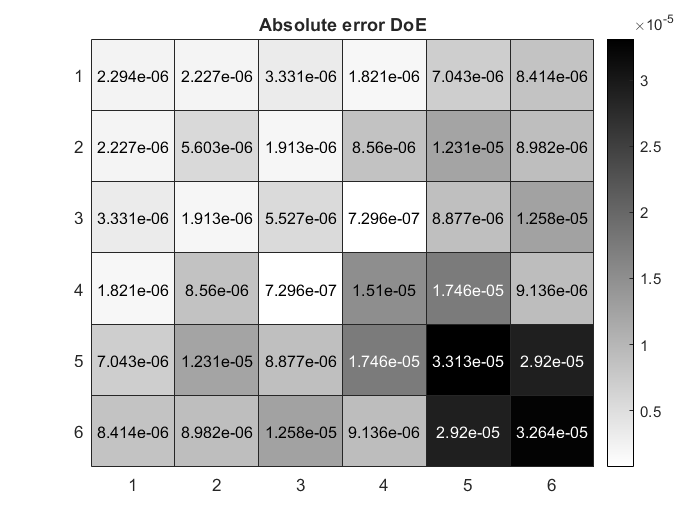

Unrecognized function or variable 'max_errors'.

lambda = 0.7;
D = duplication_matrix(n);
Q = D * transformation_matrix(n);
froeb_errors = [];
max_errors = [];

for v_sd_index = 1:length(noise_v_sd)
    for i_sd_index = 1:length(noise_i_sd)
        load_avg_pd = mpc.bus(load_mask, PD);
        load_avg_qd = mpc.bus(load_mask, QD);
        for i = 1:samples
            mpc.bus(load_mask, PD) = normrnd(load_avg_pd, random_load_power_cv * load_avg_pd);
            mpc.bus(load_mask, QD) = normrnd(load_avg_qd, random_load_power_cv * load_avg_qd);
            res = runpf(mpc);
            bus_phase = res.bus(:, VA) * pi / 180;
            bus_magnitude = res.bus(:, VM);
            bus_voltage(:, i) = bus_magnitude .* (cos(bus_phase) + sqrt(-1) * sin(bus_phase));
            load_pd(:, i) = res.bus(load_mask, PD);
            load_qd(:, i) = res.bus(load_mask, QD);
        end
        ev = normrnd(0, noise_v_sd(v_sd_index), size(bus_voltage));
        ei = normrnd(0, noise_i_sd(i_sd_index), size(bus_voltage));
        bus_current = Y * bus_voltage + ei;
        bus_voltage = bus_voltage + ev;
               
        Y1_hat = estimate_rls(bus_voltage, bus_current, D, lambda);
        [fro_err_1, max_err_1] = error_metrics(Y, Y1_hat(:, :, end), 'RLS1');

        Y2_hat = estimate_rls(bus_voltage, bus_current, Q, lambda);
        [fro_err_2, max_err_2] = error_metrics(Y, Y2_hat(:, :, end), 'RLS2');
        
        [Y_hat_doe, Z_doe, V_real_doe] = estimate_rls_doe(load_pd, load_qd, load_mask, controllable_mask, ev, ei, mpc, Q, lambda, Y);
        [fro_err_doe, max_err_doe] = error_metrics(Y, Y_hat_doe(:, :, end), 'DoE');
        
        froeb_errors = [froeb_errors; [noise_v_sd(v_sd_index) noise_i_sd(i_sd_index) fro_err_1 fro_err_2 fro_err_doe]];
        max_errors = [max_errors; [noise_v_sd(v_sd_index) noise_i_sd(i_sd_index) max_err_1 max_err_2 max_err_doe]];
    end
end

froeb_errors
max_errors